# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 10-Nov-2022 13:44:43

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 15);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Re", "S", "Ri", "xc", "yc", "Nu", "T", "Pi", "Po", "Nuw_c", "Tw_c", "Piw_c", "Pow_c", "delPdelPo", "delNudelNuo"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
data_lr = readtable("D:\4-1\Research\New Chapter- Incorporating ML\Final\All Data\All data merged ready for training.csv", opts);
data_lr(1,:)=[]

data_lr = 10920×15 table
    Re    S     Ri      xc     yc       Nu         T         Pi        Po       Nuw_c      Tw_c      Piw_c      Pow_c     delPdelPo    delNudelNuo
    __    _    _____    ___    ___    ______    _______    ______    _______    ______    _______    ______    _______    _________    ___________

    50    0      0.1    0.2    0.2    2.2891    0.14015    4.9081    0.23716    2.2656    0.13955     2.992    0.23141      1.692         1.0104  
    50    0    0.595   

## Clear temporary variables

clear opts

## **PREDICTING NUSSELT NUMBER RATIO**

**Linear Regression**

linearModel_nu=fitlm(data_lr,"quadratic","ResponseVar","delNudelNuo","PredictorVars",["Re","S","Ri","xc","yc"])

linearModel_nu = Linear regression model:
    delNudelNuo ~ 1 + Re*S + Re*Ri + Re*xc + Re*yc + S*Ri + S*xc + S*yc + Ri*xc + Ri*yc + xc*yc + Re^2 + S^2 + Ri^2 + xc^2 + yc^2

Estimated Coefficients:
                    Estimate          SE         tStat       pValue   
                   ___________    __________    _______    ___________

    (Intercept)        0.64376      0.014612     44.057              0
    Re             -0.00060996    4.1961e-05    -14.537     1.9713e-47
    S                 -0.19557     0.0075736    -25.822    9.3346e-143
    Ri                0.009355     0.0018968     4.9321     8.2564e-07
    xc                 0.40725      0.031645     12.869     1.2593e-37
    yc                  1.1858      0.031645     37.473     3.429e-

linearModel_nu.Coefficients

ans = 21×4 table
                    Estimate          SE         tStat       pValue   
                   ___________    __________    _______    ___________

    (Intercept)        0.64376      0.014612     44.057              0
    Re             -0.00060996    4.1961e-05    -14.537     1.9713e-47
    S                 -0.19557     0.0075736    -25.822    9.3346e-143
    Ri                0.009355     0.0018968     4.9321     8.2564e-07
    xc                 0.40725      0.031645     12.869     1.2593e-37
    yc                  1.1858      0.031645     37.473     3.429e-289
    Re:S           -7.6896e-05    9.6655e-06    -7.9557     1.9571e-15
    Re:Ri           1.1899e-05    2.3847e-06     4.9897     6.1421e-07


writetable(linearModel_nu.Coefficients,"D:/Matlab Drive/Research/Figure/LR/Coefficient.xlsx",'Sheet','Nu ratio')

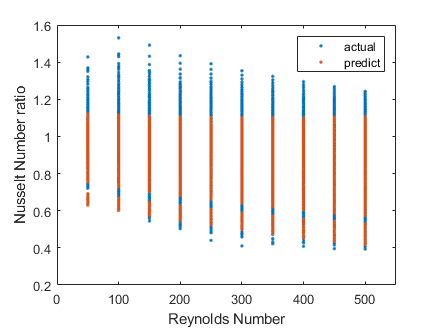

yPredict_lr_nu=predict(linearModel_nu,data_lr);

scatter(data_lr.Re,data_lr.delNudelNuo,'.')
set(gca,"Box","on")
xlabel("Reynolds Number")
ylabel("Nusselt Number ratio")
xlim([0 550])
hold on
scatter(data_lr.Re,yPredict_lr_nu,'.')
hold off
legend('actual','predict')
name_lr_nu_re=sprintf('D:/Matlab Drive/Research/Figure/Regression Models/Linear Regression Model with Re(Nusselt Num Ratio).bmp');
saveas(gcf,name_lr_nu_re)

% plot(linearModel_nu)
% ylabel('Adjusted ΔNu/ΔNuo')
% name_lr_nu=sprintf('D:/Matlab Drive/Research/Figure/Regression Models/Linear Regression Model(Nusselt Num Ratio).bmp');
% saveas(gcf,name_lr_nu)

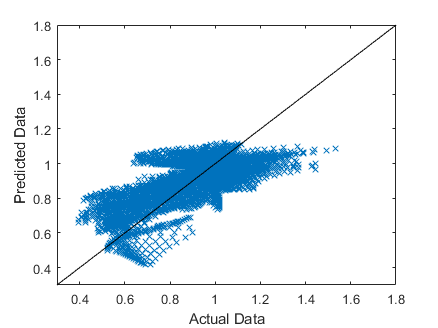

scatter(data_lr.delNudelNuo,yPredict_lr_nu,'x');hold on;
set(gca,"Box","on")
plot(0:5,0:5,'color','k')
xlim([0.3 1.8])
ylim([0.3 1.8])
xlabel("Actual Data")
ylabel("Predicted Data")
hold off
name_lr_nu=sprintf('D:/Matlab Drive/Research/Figure/Regression Models/Linear Regression Model(Nusselt Num Ratio).bmp');
saveas(gcf,name_lr_nu)

**Performence:**

yActual=data_lr.delNudelNuo;
residuals=yActual-yPredict_lr_nu;
table_1=rMetrics(yActual,yPredict_lr_nu)

table_1 = 1×5 table
      mae         mse        rmse        Rsq       mape 
    ________    ________    _______    _______    ______

    0.079835    0.011485    0.10717    0.49839    9.2413


**Tree Model**

treeModel_nu=fitrtree(data_lr,"delNudelNuo","PredictorNames",["Re","S","Ri","xc","yc"],"MinLeafSize",4)

treeModel_nu =   RegressionTree
           PredictorNames: {'Re'  'S'  'Ri'  'xc'  'yc'}
             ResponseName: 'delNudelNuo'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 10920


  Properties, Methods


% view(treeModel)

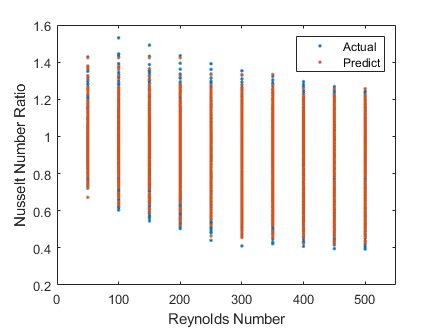

yPredict_dt_nu=predict(treeModel_nu,data_lr);

scatter(data_lr.Re,data_lr.delNudelNuo,'.')
set(gca,"Box","on")
xlim([0 550])
hold on
scatter(data_lr.Re,yPredict_dt_nu,'.')
hold off
legend('Actual','Predict')
xlabel("Reynolds Number")
ylabel("Nusselt Number Ratio")
name_dt_nu_re=sprintf('D:/Matlab Drive/Research/Figure/Regression Models/Descision Tree Model with Re(Nusselt).bmp');
saveas(gcf,name_dt_nu_re)

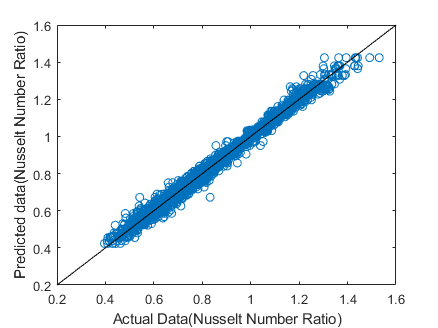

figure()
hold on
scatter(data_lr.delNudelNuo,yPredict_dt_nu)
xlabel("Actual Data(Nusselt Number Ratio)")
ylabel("Predicted data(Nusselt Number Ratio)")
set(gca,"Box","on")
plot(0:2,0:2,'color','k')
xlim([0.2 1.6])
ylim([0.2 1.6])
hold off
name_dt_nu=sprintf('D:/Matlab Drive/Research/Figure/Regression Models/Descision Tree Model(Nusselt).bmp');
saveas(gcf,name_dt_nu)

**Performence:**

yActual=data_lr.delNudelNuo;
residuals=yActual-yPredict_dt_nu;
table_2=rMetrics(yActual,yPredict_dt_nu)

table_2 = 1×4 table
      mae         mse          rmse        Rsq  
    _______    __________    ________    _______

    0.00702    0.00015294    0.012367    0.99332


## PREDICTING PRESSURE RATIO

**Linear Regression**

linearModel_p=fitlm(data_lr,"quadratic","ResponseVar","delPdelPo","PredictorVars",["Re","S","Ri","xc","yc"])

linearModel_p = Linear regression model:
    delPdelPo ~ 1 + Re*S + Re*Ri + Re*xc + Re*yc + S*Ri + S*xc + S*yc + Ri*xc + Ri*yc + xc*yc + Re^2 + S^2 + Ri^2 + xc^2 + yc^2

Estimated Coefficients:
                    Estimate          SE         tStat        pValue  
                   ___________    __________    ________    __________

    (Intercept)         3.2051      0.027996      114.48             0
    Re             -0.00094998    8.0396e-05     -11.816    5.0397e-32
    S                 -0.11892      0.014511     -8.1952    2.7813e-16
    Ri               0.0049349     0.0036342      1.3579       0.17452
    xc                 -4.2537      0.060632     -70.156             0
    yc                 -4.7342      0.060632     -78.081             0

linearModel_p.Coefficients

ans = 21×4 table
                    Estimate          SE         tStat        pValue  
                   ___________    __________    ________    __________

    (Intercept)         3.2051      0.027996      114.48             0
    Re             -0.00094998    8.0396e-05     -11.816    5.0397e-32
    S                 -0.11892      0.014511     -8.1952    2.7813e-16
    Ri               0.0049349     0.0036342      1.3579       0.17452
    xc                 -4.2537      0.060632     -70.156             0
    yc                 -4.7342      0.060632     -78.081             0
    Re:S            0.00017804    1.8519e-05      9.6141    8.5105e-22
    Re:Ri          -1.6391e-05     4.569e-06     -3.5875    0.00033532


writetable(linearModel_p.Coefficients,"D:/Matlab Drive/Research/Figure/LR/Coefficient.xlsx",'Sheet','Pressure ratio')

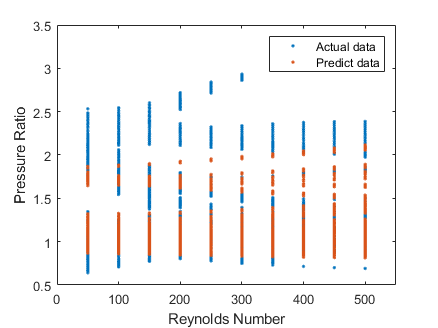

yPredict_lr_p=predict(linearModel_p,data_lr);

scatter(data_lr.Re,data_lr.delPdelPo,'.')
set(gca,"Box","on")
xlim([0 550])
xlabel('Reynolds Number')
ylabel('Pressure Ratio')
hold on
scatter(data_lr.Re,yPredict_lr_p,'.')
hold off
legend('Actual data','Predict data')
name_lr_p_re=sprintf('D:/Matlab Drive/Research/Figure/Regression Models/Linear Regression Model with Re(Pressure Ratio).bmp');
saveas(gcf,name_lr_p_re)

% plot(linearModel_p)
% ylabel('Adjusted ΔP/ΔPo')
% name_lr_p=sprintf('D:/Matlab Drive/Research/Figure/Regression Models/Linear Regression Model(Pressure Ratio).bmp');
% saveas(gcf,name_lr_p)

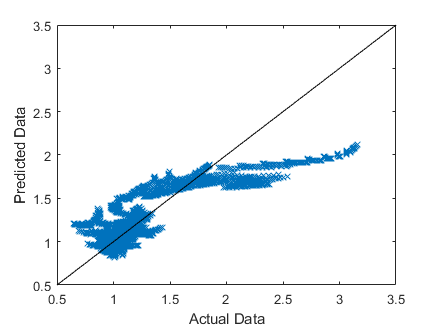

scatter(data_lr.delPdelPo,yPredict_lr_p,'x');hold on;
set(gca,"Box","on")
plot(0:5,0:5,'color','k')
xlim([0.5 3.5])
ylim([0.5 3.5])
xlabel("Actual Data")
ylabel("Predicted Data")
hold off
name_lr_p=sprintf('D:/Matlab Drive/Research/Figure/Regression Models/Linear Regression Model(Pressure Ratio).bmp');
saveas(gcf,name_lr_p)

**Performence:**

yActual=data_lr.delPdelPo;
residuals=yActual-yPredict_lr_p;
table_3=rMetrics(yActual,yPredict_lr_p)

table_3 = 1×5 table
      mae        mse       rmse        Rsq       mape 
    _______    _______    _______    _______    ______

    0.13964    0.04216    0.20533    0.63855    11.885


**Tree Model**

treeModel_p=fitrtree(data_lr,"delPdelPo","PredictorNames",["Re","S","Ri","xc","yc"],"MinLeafSize",4)

treeModel_p =   RegressionTree
           PredictorNames: {'Re'  'S'  'Ri'  'xc'  'yc'}
             ResponseName: 'delPdelPo'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 10920


  Properties, Methods


% view(treeModel)

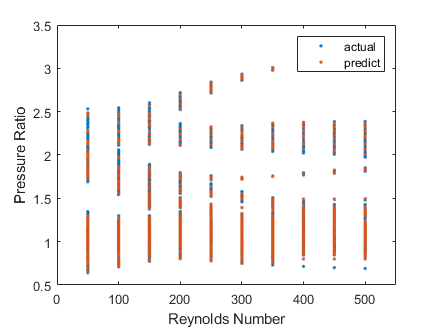

yPredict_dt_p=predict(treeModel_p,data_lr);

scatter(data_lr.Re,data_lr.delPdelPo,'.')
set(gca,"Box","on")
xlim([0 550])
hold on
scatter(data_lr.Re,yPredict_dt_p,'.')
hold off
legend('actual','predict')
xlabel("Reynolds Number")
ylabel("Pressure Ratio")
name_dt_p_re=sprintf('D:/Matlab Drive/Research/Figure/Regression Models/Descision Tree Model(Pressure) with Re.bmp');
saveas(gcf,name_dt_p_re)

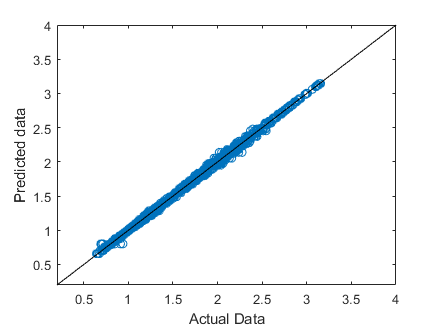

figure()
hold on
scatter(data_lr.delPdelPo,yPredict_dt_p)
xlabel("Actual Data")
ylabel("Predicted data")
set(gca,"Box","on")
plot(0:5,0:5,'color','k')
xlim([0.2 4])
ylim([0.2 4])
hold off
name_dt_p=sprintf('D:/Matlab Drive/Research/Figure/Regression Models/Descision Tree Model(Pressure ration).bmp');
saveas(gcf,name_dt_p)

**Performence:**

yActual=data_lr.delPdelPo;
residuals=yActual-yPredict_dt_p;
table_4=rMetrics(yActual,yPredict_dt_p)

table_4 = 1×4 table
       mae          mse          rmse         Rsq  
    _________    __________    _________    _______

    0.0059033    9.8706e-05    0.0099351    0.99915


**All Together**

Table=cat(1,table_1,table_2,table_3,table_4);
Property={'ΔNu/ΔNuo(Linear Regression)';'ΔNu/ΔNuo(Decision Tree)';'ΔP/ΔPo(Linear Regression)';'ΔP/ΔPo(Decision Regression)'};
Table=addvars(Table,Property,'Before',"mae")

Table = 4×5 table
               Property                   mae          mse          rmse         Rsq  
    _______________________________    _________    __________    _________    _______

    {'ΔNu/ΔNuo(Linear Regression)'}     0.079835      0.011485      0.10717    0.49839
    {'ΔNu/ΔNuo(Decision Tree)'    }      0.00702    0.00015294     0.012367    0.99332
    {'ΔP/ΔPo(Linear Regression)'  }      0.13964       0.04216      0.20533    0.63855
    {'ΔP/ΔPo(Decision Regression)'}    0.0059033    9.8706e-05    0.0099351    0.99915


writetable(Table,"D:/Matlab Drive/Research/Table/Performence of Regression models.xlsx")